%close all
%clear
%clc

## Cargar datos


%load("data_for_animation.mat");

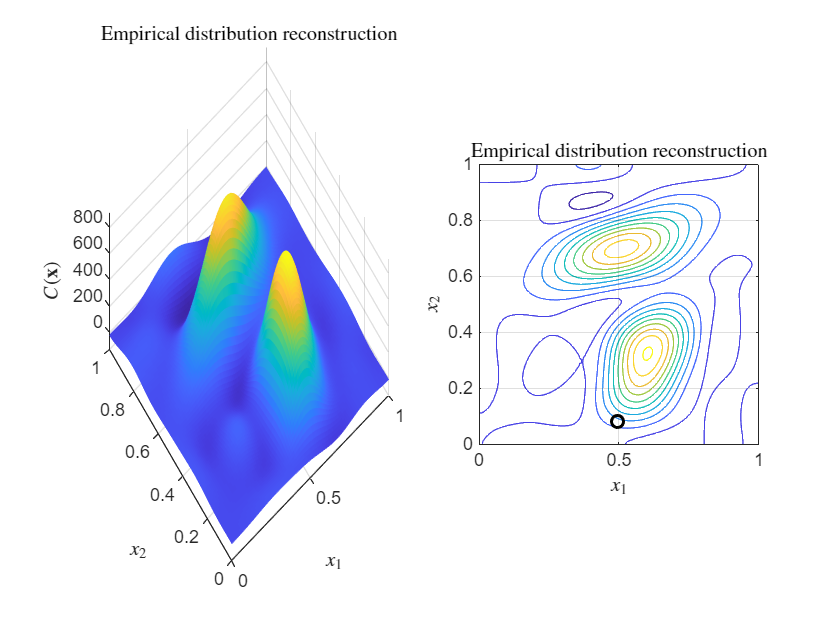


%Empirical distribution animation 1st Order system

figure(5)

for i = 1:length(t_1)

    subplot(1,2,1);
    surf(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)))
    view([-38 63])
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Empirical distribution reconstruction",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    zlabel('$C(\mathbf{x})$','Interpreter','latex')
    axis tight
    shading flat
    colormap default
    grid on

    subplot(1,2,2);
    contour(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)))
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Empirical distribution reconstruction",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    axis equal
    grid on
    hold on
    plot(estados(i,1), estados(i,2), 'ko', 'LineWidth', 1.5)
    hold off

    drawnow limitrate

end

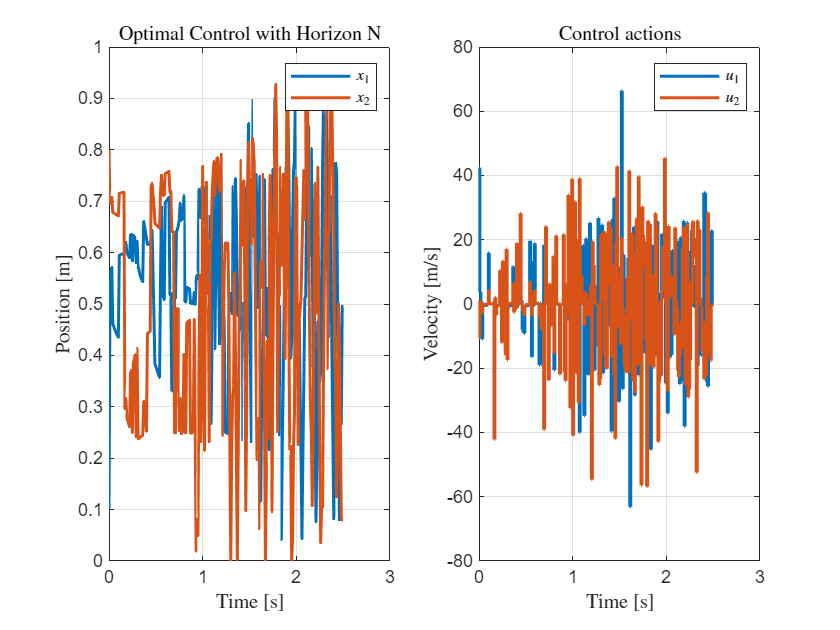

%Plots
figure(1)
subplot(1,2,1)
plot(t_1, estados, 'LineWidth', 1.5)
title("Optimal Control with Horizon N",'Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('Position [m]','Interpreter','latex')
legend('$x_1$', '$x_2$','Interpreter','latex')
grid on
subplot(1,2,2)
stairs(t_1, controles, 'LineWidth', 1.5)
title("Control actions",'Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('Velocity [m/s]','Interpreter','latex')
legend('$u_1$', '$u_2$','Interpreter','latex')
grid on

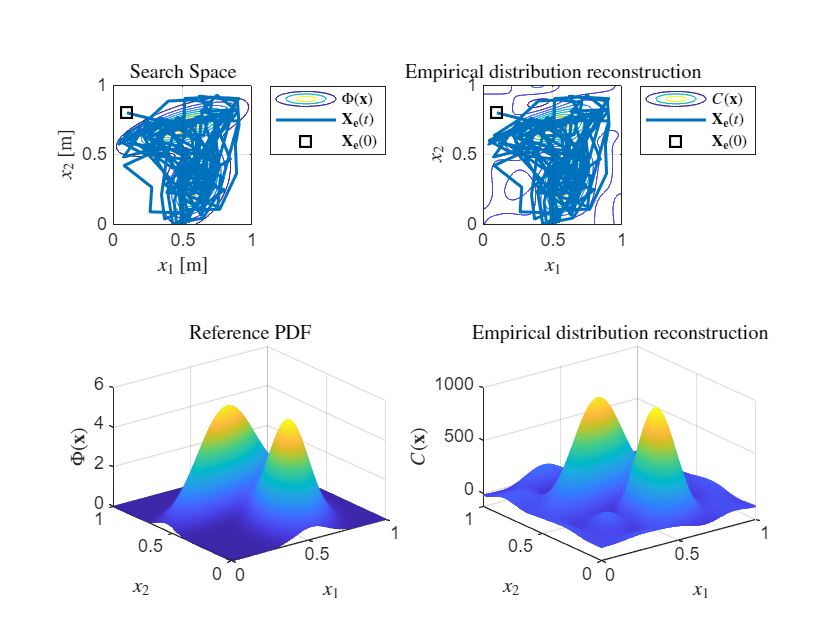


figure(2)
subplot(2,2,1);
contour(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Search Space",'Interpreter','latex')
xlabel('$x_1$ [m]','Interpreter','latex')
ylabel('$x_2$ [m]','Interpreter','latex')
axis equal
grid on
hold on
plot(estados(:,1),estados(:,2),'LineWidth',1.5)
plot(estados(1,1),estados(1,2),'ksq','MarkerSize',7,'LineWidth',1.5)
legend('$\Phi(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
    'Interpreter','latex','Location','northeastoutside')
% comet(estados(:,1),estados(:,2))
hold off
subplot(2,2,2);
contour(x_1_grid, x_2_grid, reshape(C_x, length(x_2), length(x_1)))
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Empirical distribution reconstruction",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
axis equal
grid on
hold on
plot(estados(:,1),estados(:,2),'LineWidth',1.5)
plot(estados(1,1),estados(1,2),'ksq','MarkerSize',7,'LineWidth',1.5)
legend('$C(\mathbf{x})$','$\mathbf{X_e}(t)$', '$\mathbf{X_e}(0)$',...
    'Interpreter','latex','Location','northeastoutside')
% comet(estados(:,1),estados(:,2))
hold off
subplot(2,2,3);
surf(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)), 'EdgeColor','interp')
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Reference PDF",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$\Phi(\mathbf{x})$','Interpreter','latex')
grid on
subplot(2,2,4);
surf(x_1_grid, x_2_grid, reshape(C_x, length(x_2), length(x_1)), 'EdgeColor','interp')
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Empirical distribution reconstruction",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$C(\mathbf{x})$','Interpreter','latex')
grid on

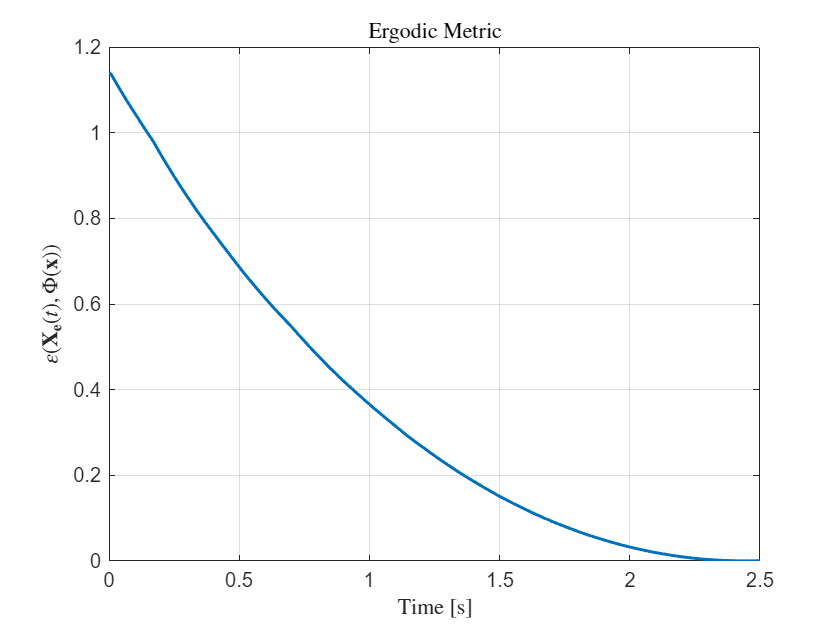


figure(3)
plot(t_1, metrica, "LineWidth",1.5)
title("Ergodic Metric",'Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\varepsilon \left( \mathbf{X_e}(t), \Phi(\mathbf{x}) \right) $','Interpreter','latex')
grid on